**Parametric Cycle Analysis** for Turbofan and Turbojet with AB

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 8

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 4

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 2

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

pi_f = 1.6000

pi_f


M19 = 0.9286

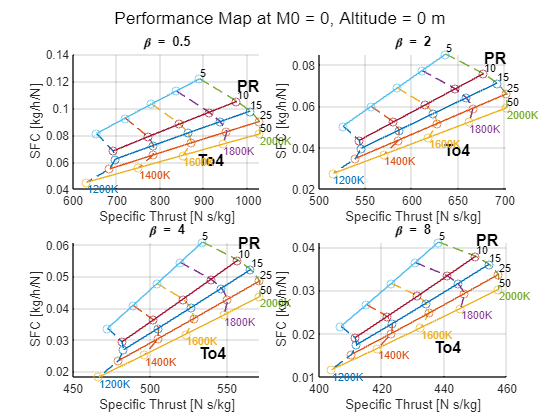

Table = 100×6 table
    Beta    PR    To4 (K)    SFC (kg/h/N)    ST (N s/kg)    ma (kg/s)
    ____    __    _______    ____________    ___________    _________

    0.5      5     1200         0.08105        653.92        170.06  
    0.5      5     1400        0.092552        719.67        154.52  
    0.5      5     1600         0.10301         780.2        142.53  
    0.5      5     1800         0.11266        836.87        132.88  
    0.5      5     2000         0.12167        890.53        124.88  
    0.5     10     1200         0.06821        692.14        160.67  
    0.5     10     1400        0.078733        772.04        144.04  
    0.5     10     1600        0.088205        844.75        131.64  
    0.5     10     1800        0.096892        912.26         121.9  
    0

Maximum ma value and its associated variables are:


    Beta    PR    To4 (K)    SFC (kg/h/N)    ST (N s/kg)    ma (kg/s)
    ____    __    _______    ____________    ___________    _________

     8      50     1200        0.011716          404         275.26  



clear; clc; close all;

% Define constants
T_sls = 25000*4.44822; % unit: N
Gc = 7/5; Gh = 4/3; % different gamma for the vitiated air 
R = 287; dHB = 4.3e7; % unit: J/kg
To4 = [1200, 1400, 1600, 1800, 2000]; % Turbine inlet temperatures, unit: K
PR = [5, 10, 15, 25, 50]; % Pressure ratios
beta = [0.5, 2, 4, 8]; % Bypass ratios
pi_f = [8, 4, 2, 1.6]; % Fan pressure ratio
To7 = [2200, 2400, 2600, 2800]; % AB inlet temperatures, unit: K

% Conditions for each figure
conditions = [0, 0];%  1.7, 16764]; % Each row: [M0, H (m)]5, 24384;

for c = 1:size(conditions, 1)
    M0 = conditions(c, 1);
    H = conditions(c, 2);
    
    [T0, a0, P0, rho0] = atmosisa(H); % Get atmospheric properties using International Standard Atmosphere, H (m)

    % Initialize a cell array to store data (preallocate size)
    dataCell = {};

    % Create a figure
    figure;
    hold on;
    sgtitle(sprintf('Performance Map at M0 = %g, Altitude = %g m', M0, H)); % Main title with M0 and H
    % Add text for dashed and solid curves description
    text(0.5, 0.5, 'To4 (dashed curves), PR (solid curves)', ...
    'Units', 'normalized', 'FontSize', 8, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top');
    colors = lines(length(To4));
    
    % Loop over different beta values
    for k = 1:length(beta)
        subplot(2, 2, k);
        grid on;
        hold on;

        % Compute performance metrics for current beta
        [SFC, ST] = idealengine(pi_f(k), beta(k), 0, To4, PR, P0, T0, M0, dHB, Gc, Gh, R);
        % [SFC, ST] = idealengine(0, 0, To7(k), To4, PR, P0, T0, M0, dHB, Gc, Gh, R);

        % Plot lines for constant To4
        for j = 1:length(To4)
            % Get the coordinate limits for the current subplot
            y_min = min(SFC(:)); y_max = max(SFC(:)); y_range = y_max - y_min;
            x_min = min(ST(:)); x_max = max(ST(:)); x_range = x_max - x_min;

            plot(ST(:, j), SFC(:, j), '--', 'Color', colors(j, :));
            % Labeling To4 at the start of each curve
            text(ST(end, j), SFC(end, j), [num2str(To4(j)) 'K'], ...
                'VerticalAlignment', 'top', 'HorizontalAlignment', 'left', ...
                'Color', colors(j, :), 'FontSize', 8);
            % Labeling "To4"
            if j == 1
                text(ST(ceil(size(ST, 1) / 2), ceil(size(ST, 1) / 2))+0.05*x_range, SFC(ceil(size(SFC, 1) / 2), j)-0.1*y_range,...
                    'To4', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', ...
                    'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold');
            end
        end
    
        % Plot lines for constant PR
        for i = 1:length(PR)
            y_min = min(SFC(:)); y_max = max(SFC(:)); y_range = y_max - y_min;  % Get the coordinate limits for the current subplot

            plot(ST(i, :), SFC(i, :), 'Marker', 'o');
            % Labeling PR at the end of each curve
            text(ST(i, end), SFC(i, end), [num2str(PR(i))], ...
                'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left',...
                'Color', 'k', 'FontSize', 8);
            % Labeling "PR"
            if i == 1
                text(ST(2, 5), SFC(2, 5)+0.05*y_range, 'PR', ...
                    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', ...
                    'Color', 'k', 'FontSize', 12, 'FontWeight', 'bold');
            end
        end

        xlabel('Specific Thrust [N s/kg]');
        ylabel('SFC [kg/h/N]');
        title(['\beta = ' num2str(beta(k))], 'FontSize', 10);
        % title(['To7 = ' num2str(To7(k)) 'K'] , 'FontSize', 10);
        hold off;
        
        % Store data in the cell array
        for i = 1:length(PR)
            for j = 1:length(To4)
                dataCell{end + 1, 1} = beta(k);
                dataCell{end, 2} = PR(i);
                dataCell{end, 3} = To4(j);
                dataCell{end, 4} = SFC(i, j);
                dataCell{end, 5} = ST(i, j); 
                ma = T_sls ./ ST(i, j);
                dataCell{end, 6} = ma;                
            end
        end

    end
    % Convert the cell array to a table and set variable names
    Table = cell2table(dataCell, 'VariableNames', {'Beta', 'PR', 'To4 (K)', 'SFC (kg/h/N)', 'ST (N s/kg)', 'ma (kg/s)'})
    
    %disp(Table); % Display the results

    % Extract the 'ma' column from the table
    ma_values = Table{:,'ma (kg/s)'};
    
    % Find the maximum value and its index
    [max_ma, ind] = max(ma_values);
    
    % Extract the row with the maximum value of 'ma'
    max_row = Table(ind, :);
    
    % Display the result
    disp('Maximum ma value and its associated variables are:');
    disp(max_row);


    
end

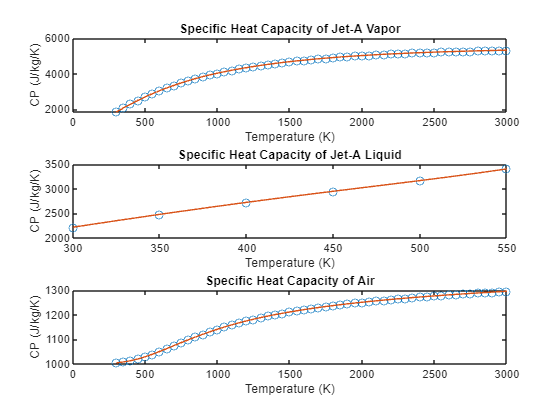

CPJA_v = 5.0200e+03

CPa_v = 1.2506e+03


[CPJA_v, CPa_v] = CP_f(2000, true)

**Cp curve fitting**

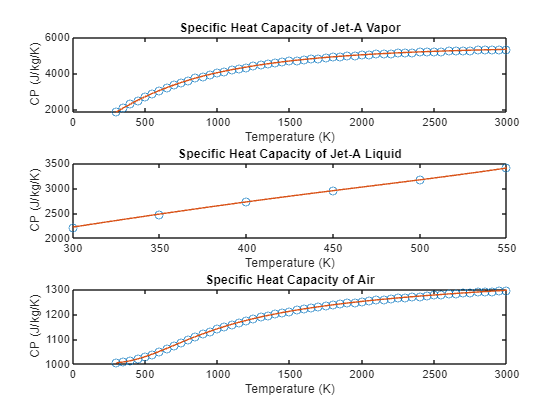

clear; clc; close all;

% Load data
data = readtable('C:\Users\SJ Chen\OneDrive - purdue.edu\Purdue\2024Fall\AAE538 Air-Breathing Propulsion\Project\Specificheat.csv'); 

T = data.T;   % Temperature in K
CPJAg = data.CPJAg; % Specific heat of Jet-A vapor in J/kg/K
CPJAL = data.CPJAL; % Specific heat of Jet-A liquid in J/kg/K
CPa = data.CPa; % Specific heat of air in J/kg/K

% Create spline representations of the variables
CPJAg_spline = spline(T, CPJAg);
CPJAL_spline = spline(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)));  % Use only non-NaN entries
CPa_spline = spline(T, CPa);

% Define a finer temperature range for plotting the splines
T_fine = linspace(min(T), max(T), 300);
T_fine_JL = linspace(min(T(~isnan(CPJAL))), max(T(~isnan(CPJAL))), 300);  % Only within the valid range of CPJ8L

% Evaluate splines on the finer temperature grid
CPJAg_fine = ppval(CPJAg_spline, T_fine);
CPJAL_fine = ppval(CPJAL_spline, T_fine_JL);
CPa_fine = ppval(CPa_spline, T_fine);

% Plotting
figure;

% Specific heat of Jet-A vapor
subplot(3,1,1); 
plot(T, CPJAg, 'o', T_fine, CPJAg_fine, '-'); 
title('Specific Heat Capacity of Jet-A Vapor'); xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

% Specific heat of Jet-A liquid
subplot(3,1,2); 
plot(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)), 'o', T_fine_JL, CPJAL_fine, '-'); 
title('Specific Heat Capacity of Jet-A Liquid'); xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

% Specific heat of air
subplot(3,1,3); 
plot(T, CPa, 'o', T_fine, CPa_fine, '-'); 
title('Specific Heat Capacity of Air'); xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

function [SFC, ST] = idealengine(pi_f, beta, To7, To4, PR, P0, T0, M0, dHB, Gc, Gh, R)
    
    % Define the constants
    Cpc = Gc * R / (Gc - 1); Cph = Gh * R / (Gh - 1);
    Ed = 1; Ec = 1; Eb = 1; Et = 1; En = 1; Eab = 1; Ef = 1;
    %Ed = 0.97; Ec = 0.85; Eb = 0.98; Et = 0.91; En = 0.96; Eab = 0.98; Ef= 0.87;

    % Preallocate the matrices to store results
    SFC = zeros(length(PR), length(To4));
    ST = zeros(length(PR), length(To4));
    
    T19 = T0;
        
    % station 0
    u0 = M0 * sqrt(Gc * R *T0);
    
    for i = 1:length(PR)
        for j = 1:length(To4)
            % station 2
            To2 = T0 * (1 + (Gc-1)/2 * M0^2);
            Po2 = P0 * (1 + Ed * (Gc-1)/2 * M0^2)^(Gc/(Gc-1));
            
            % station 3
            Po3 = PR(i) * Po2;
            To3 = To2 * (1 + (PR(i)^((Gc-1)/Gc) - 1) / Ec);
            
            % station 4
            Po4 = Po3;
            
            f = (Cph*To4(j) - Cpc*To3) / (Eb*dHB - Cph*To4(j));
            
            % station 5
            M19 = 1; % choke at the nozzle
            To13_19choke = T19 * (1 + (Gh-1)/2 * M19^2);
            
            To13_fPR = To2 * (1 + (pi_f^((Gc-1)/Gc) - 1) / Ef);
            if To13_fPR >= To13_19choke
                To13 = To13_19choke;
            else
                To13 = To13_fPR;
                disp('pi_f');
                M19 = sqrt(2/(Gh-1) * (To13/T19 - 1));
            end
            
            To5 = To4(j) - (Cpc/Cph)/(1 + f) * ((To3 - To2) - beta*(To13-To2));
            Po5 = Po4 * (1 - ((1 - To5/To4(j)) / Et))^(Gh/(Gh-1));
            
            if f < 0 || To5 < 0
                continue % The engine can't operate at this flight condition; skip the current iteration
            end

            % station 7
            Po7 = Po5;
            
            fab = (1+f) * (Cph*To7 - Cpc*To5) / (Eab*dHB - Cph*To7);
            
            % station 9
            u9_f = sqrt(2*Cph*To5*En * ( 1-(P0/Po5)^((Gh-1)/Gh) ));
            u9_ab = sqrt(2*Cph*To7*En * ( 1-(P0/Po7)^((Gh-1)/Gh) ));
            
            % Calculate Specific Thrust and SFC
            if beta ==0
                u9 = u9_ab;
            else
                u9 = u9_f;
                fab = 0;
            end
            
            ST(i, j) = (1+f+fab)/(1+beta)*u9 - 1/(1+beta)*u0 + beta/(1+beta) ...
                * (M19*sqrt(Gc*R*T19) - M0*sqrt(Gc*R*T0));
            SFC(i, j) = (f + fab) / ST(i, j) / (1+beta) * 3600;
        end
    end
    
end

**Cp curve fitting**

function [CPJA_v, CPa_v] = CP_f(Tin, showPlot)
    % returns specific heat values for Jet-A vapor, Jet-A liquid, and air
    % INPUTS-showPlot: Boolean flag to indicate whether to show plots (true/false)
   
    % Load data
    data = readtable('C:\Users\SJ Chen\OneDrive - purdue.edu\Purdue\2024Fall\AAE538 Air-Breathing Propulsion\Project\Specificheat.csv'); 

     T = data.T;          % Temperature in K
    CPJAg = data.CPJAg;  % Specific heat of Jet-A vapor in J/kg/K
    CPJAL = data.CPJAL;  % Specific heat of Jet-A liquid in J/kg/K
    CPa = data.CPa;      % Specific heat of air in J/kg/K

    % Create spline representations of the variables
    CPJAg_spline = spline(T, CPJAg);
    CPJAL_spline = spline(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)));  % Use only non-NaN entries
    CPa_spline = spline(T, CPa);

    % Check if input temperature is within the range of the data
    if Tin < min(T) || Tin > max(T)
        error('Input temperature is out of range of the available data.');
    end

    % Evaluate specific heat for air at the input temperature
    CPa_v = ppval(CPa_spline, Tin);

    % Determine specific heat for Jet-A (liquid or vapor depending on temperature)
    if Tin <= max(T(~isnan(CPJAL)))
        % If the temperature is within the range of Jet-A liquid, use CPJAL
        CPJA_v = ppval(CPJAL_spline, Tin);
    else
        % Otherwise, use Jet-A vapor specific heat
        CPJA_v = ppval(CPJAg_spline, Tin);
    end

    % Plotting if showPlot is true
    if showPlot
        % Define a finer temperature range for plotting the splines
        T_fine = linspace(min(T), max(T), 300);
        T_fine_JL = linspace(min(T(~isnan(CPJAL))), max(T(~isnan(CPJAL))), 300);  % Only within the valid range of CPJAL

        % Evaluate splines on the finer temperature grid
        CPJAg_fine = ppval(CPJAg_spline, T_fine);
        CPJAL_fine = ppval(CPJAL_spline, T_fine_JL);
        CPa_fine = ppval(CPa_spline, T_fine);

        % Plotting
        figure;

        % Specific heat of Jet-A vapor
        subplot(3,1,1); 
        plot(T, CPJAg, 'o', T_fine, CPJAg_fine, '-'); 
        title('Specific Heat Capacity of Jet-A Vapor'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

        % Specific heat of Jet-A liquid
        subplot(3,1,2); 
        plot(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)), 'o', T_fine_JL, CPJAL_fine, '-'); 
        title('Specific Heat Capacity of Jet-A Liquid'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

        % Specific heat of air
        subplot(3,1,3); 
        plot(T, CPa, 'o', T_fine, CPa_fine, '-'); 
        title('Specific Heat Capacity of Air'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');
    end
end

